## continuous representation

syms fc xc;
fc = 1+xc*sin(xc)*sin(xc)

$$fc = \mathrm{xc}\,{\sin\left(\mathrm{xc}\right)}^{2}+1$$


% interval start point
x0 = 0;
% interval end point
x1 = 2*pi;

% moments for continuous signal
fc_mean = 1/(x1-x0)*int(fc,xc,[x0,x1]);
fc_std = sqrt(1/(x1-x0)*int( (fc-fc_mean)^2 ,xc,[x0,x1]));
fc_skew = ( 1/(x1-x0)*int( (fc-fc_mean)^3 ,xc,[x0,x1]) ) ...
    / fc_std^3;
fc_kurt = ( 1/(x1-x0)*int( (fc-fc_mean)^4 ,xc,[x0,x1]) ) ...
    / fc_std^4;

disp([eval(fc_mean), eval(fc_std), eval(fc_skew), eval(fc_kurt)]);

    2.5708    1.4943    0.8918    2.5384



## discrete representation

% number of points
nx = 1001;

xd = linspace(x0,x1,nx);
% xd = logspace(-1,log10(x1),nx);
fd = 1+xd.*sin(xd).*sin(xd);

% verification function
% rng('default');
% fd = normrnd(0,1,[1,nx]);


% moments for discrete signal
fd_mean = 1/(x1-x0)*trapz(xd,fd);%mean(fd);
fd_std = sqrt(1/(x1-x0)*trapz( xd,(fd-fd_mean).^2));%std(fd);
fd_skew = ( 1/(x1-x0)*trapz( xd,(fd-fd_mean).^3) ) / fd_std^3;%skewness(fd);
fd_kurt = ( 1/(x1-x0)*trapz( xd,(fd-fd_mean).^4) ) / fd_std^4;%kurtosis(fd);

disp([fd_mean, fd_std, fd_skew, fd_kurt]);

    2.5708    1.4943    0.8918    2.5384



## visualisation

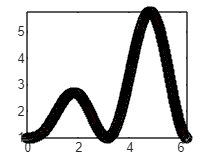

fplot(fc,[x0,x1],'-r',LineWidth=2)
hold on
plot(xd,fd,'ko')